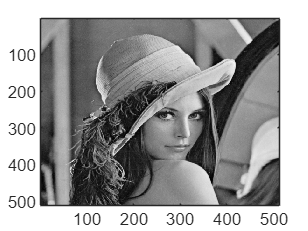

clear all
close all
img = im2double(imread("standard_test_images\lena_gray_512.tif"));
img = img(:,:,1);
colormap gray
imagesc(img)

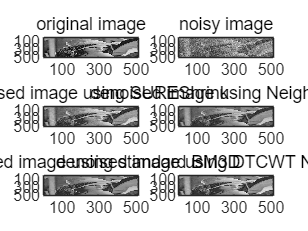

Error: profile not found! Returning default profile.


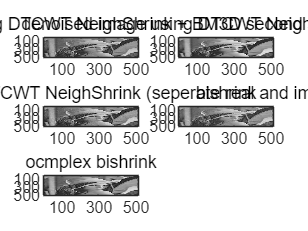

    "noise variance:"    "40.319"

    "noisy image PSNR/SSIM:"    "16.0267"    " / "    "0.14918"

    "PSNR/SSIM after SURE:"    "27.0279"    " / "    "0.70205"

    "PSNR/SSIM after NeighShrink:"    "27.2873"    " / "    "0.69477"

    "PSNR/SSIM after standard BM3D:"    "29.9616"    " / "    "0.82075"

    "PSNR/SSIM after CWT Neighshrink + BM3D second stage:"    "29.4889"    " / "    "0.79708"

    "PSNR/SSIM after CWT Neighshrink + BM3D:"    "29.4174"    " / "    "0.8145"

    "PSNR/SSIM after CWT NeighShrink:"    "28.7697"    " / "    "0.75565"

    "PSNR/SSIM after CWT NeighShrink (seperate real and imag parts):"    "28.1224"    " / "    "0.70563"

    "PSNR/SSIM after BiShrink:"    "27.5372"    " / "    "0.72421"

    "PSNR/SSIM after CWT BiShrink:"    "29.0127"    " / "    "0.80099"



noise_var = 0.025;
[PSNR,SNR,ssim,img_den] = den_compare(img,noise_var,0);

sweep_std = 10:5:50;
sweep_var = (sweep_std./255).^2;
PSNR_noisy = zeros(1,length(sweep_var));
PSNR_sure = zeros(1,length(sweep_var));
PSNR_neigh = zeros(1,length(sweep_var));
PSNR_BM3D_standard = zeros(1,length(sweep_var));
PSNR_neigh_complex = zeros(1,length(sweep_var));
PSNR_BM3D_complex_2nd = zeros(1,length(sweep_var));
PSNR_BM3D_complex = zeros(1,length(sweep_var));
PSNR_neigh_complex_real_imag = zeros(1,length(sweep_var));
PSNR_bi = zeros(1,length(sweep_var));
PSNR_bi_complex = zeros(1,length(sweep_var));


SSIM_noisy = zeros(1,length(sweep_var));
SSIM_sure = zeros(1,length(sweep_var));
SSIM_neigh = zeros(1,length(sweep_var));
SSIM_BM3D_standard = zeros(1,length(sweep_var));
SSIM_neigh_complex = zeros(1,length(sweep_var));
SSIM_BM3D_complex_2nd = zeros(1,length(sweep_var));
SSIM_BM3D_complex = zeros(1,length(sweep_var));
SSIM_neigh_complex_real_imag = zeros(1,length(sweep_var));
SSIM_bi = zeros(1,length(sweep_var));
SSIM_bi_complex = zeros(1,length(sweep_var));

%for var=sweep_var
parfor i=1:length(sweep_var)
    [PSNR_t,SNR_t,SSIM_t,~] = den_compare(img,sweep_var(i),0);
    close all
    %PSNR_noisy(cnt) = PSNR_t(1);
    PSNR_noisy(i) = PSNR_t(1);
    PSNR_sure(i) = PSNR_t(2)-PSNR_t(1);
    PSNR_neigh(i) = PSNR_t(3)-PSNR_t(1);
    PSNR_BM3D_standard(i) = PSNR_t(4)-PSNR_t(1);
    PSNR_neigh_complex(i) = PSNR_t(5)-PSNR_t(1);
    PSNR_BM3D_complex_2nd(i) = PSNR_t(6)-PSNR_t(1);
    PSNR_BM3D_complex(i) = PSNR_t(7)-PSNR_t(1);
    PSNR_neigh_complex_real_imag(i) = PSNR_t(8)-PSNR_t(1);
    PSNR_bi(i) = PSNR_t(9)-PSNR_t(1);
    PSNR_bi_complex(i) = PSNR_t(10)-PSNR_t(1);

    SSIM_noisy(i) = SSIM_t(1);
    SSIM_sure(i) = SSIM_t(2)-SSIM_t(1);
    SSIM_neigh(i) = SSIM_t(3)-SSIM_t(1);
    SSIM_BM3D_standard(i) = SSIM_t(4)-SSIM_t(1);
    SSIM_neigh_complex(i) = SSIM_t(5)-SSIM_t(1);
    SSIM_BM3D_complex_2nd(i) = SSIM_t(6)-SSIM_t(1);
    SSIM_BM3D_complex(i) = SSIM_t(7)-SSIM_t(1);
    SSIM_neigh_complex_real_imag(i) = SSIM_t(8)-SSIM_t(1);
    SSIM_bi(i) = SSIM_t(9)-SSIM_t(1);
    SSIM_bi_complex(i) = SSIM_t(10)-SSIM_t(1);

    %cnt = cnt+1;
end

Error: profile not found! Returning default profile.
    "noise variance:"    "50"

    "noisy image PSNR/SSIM:"    "14.1575"    " / "    "0.11072"

    "PSNR/SSIM after SURE:"    "26.1229"    " / "    "0.66665"

    "PSNR/SSIM after NeighShrink:"    "26.1949"    " / "    "0.64712"

    "PSNR/SSIM after standard BM3D:"    "28.9643"    " / "    "0.79714"

    "PSNR/SSIM after CWT Neighshrink + B..."    "28.4405"    " / "    "0.76607"

    "PSNR/SSIM after CWT Neighshrink + B..."    "28.4469"    " / "    "0.79259"

    "PSNR/SSIM after CWT NeighShrink:"    "27.6466"    " / "    "0.71252"

    "PSNR/SSIM after CWT NeighShrink (se..."    "26.9021"    " / "    "0.65012"

    "PSNR/SSIM after BiShrink:"    "26.5319"    " / "    "0.68983"

    "PSNR/SSIM after CWT BiShrink:"    "28.0344"    " / "    "0.77913"

Error: profile not found! Returning default profile.
    "noise variance:"    "35"

    "noisy image PSNR/SSIM:"    "17.2555"    " / "    "0.17934"

    "PSNR/SSIM after SURE:"    "27.6

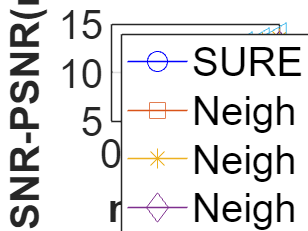

figure
plot(sweep_std,PSNR_sure,'b-o','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh,'-s','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_standard,'-+','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh_complex,'-*','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_complex_2nd,'-.','MarkerSize',10)
hold on
%plot(sweep_std,PSNR_BM3D_complex,'-x','MarkerSize',10)
hold on
plot(sweep_std,PSNR_neigh_complex_real_imag,'-d','MarkerSize',10)
hold on
plot(sweep_std,PSNR_bi,'-^','MarkerSize',10)
hold on
plot(sweep_std,PSNR_bi_complex,'-<','MarkerSize',10)
set(gca,'fontsize', 20) 



% legend('SURE','Neigh','BM3D standard','Neigh complex','BM3D complex 2nd','BM3D complex','Neigh complex seperate','Location','northwest', ...
%     'FontSize',12)
legend('SURE','Neigh','Neigh complex','Neigh complex seperate','Bi','Bi complex','Location','northwest', ...
     'FontSize',20)
xlabel('noise std','FontSize',20,'FontWeight','bold')
ylabel('PSNR-PSNR(noisy)','FontSize',20,'FontWeight', 'bold')


grid on

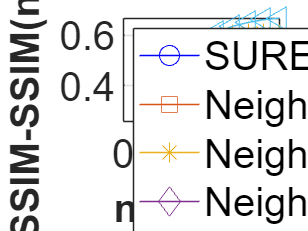

figure
plot(sweep_std,SSIM_sure,'b-o','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh,'-s','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_standard,'-+','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh_complex,'-*','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_complex_2nd,'-.','MarkerSize',10)
hold on
%plot(sweep_std,SSIM_BM3D_complex,'-x','MarkerSize',10)
hold on
plot(sweep_std,SSIM_neigh_complex_real_imag,'-d','MarkerSize',10)
hold on
plot(sweep_std,SSIM_bi,'-^','MarkerSize',10)
hold on
plot(sweep_std,SSIM_bi_complex,'-<','MarkerSize',10)
set(gca,'fontsize', 20) 

% legend('SURE','Neigh','BM3D standard','Neigh complex','BM3D complex 2nd','BM3D complex','Neigh complex seperate','Location','northwest', ...
%     'FontSize',12)
legend('SURE','Neigh','Neigh complex','Neigh complex seperate','Bi','Bi complex','Location','northwest', ...
     'FontSize',20)
xlabel('noise std','FontSize',20,'FontWeight','bold')
ylabel('SSIM-SSIM(noisy)','FontSize',20,'FontWeight', 'bold')


grid on